# Linear Regression

## Introduction

Linear regression is a statistical model that is used to predict the value of a continuous dependent variable (the response variable) based on the value of one or more independent variables (the predictor variables). It is based on the assumption that there is a linear relationship between the predictor variables and the response variable.

Regression is the method of adjusting parameters in a model to minimize the difference between the predicted output and the measured output. The predicted output is calculated from a measured input (univariate), multiple inputs and a single output (multiple linear regression), or multiple inputs and outputs (multivariate linear regression).

- linear regression: x and y are scalars

- multiple linear regression: x is a vector, y is a scalar response

- multivariate linear regression: x is a vector, y is a vector response

In machine learning terminology, the data inputs (*x*) are *features* and the measured outputs (*y*) are *labels*. For a single input and single output, *m* is the slope and *c* is the intercept.


$$y=mx+c$$


An alternate way to write this is in matrix form and changing the slope to β1 and the intercept to β2.


$$y=\left\lbrack \begin{array}{cc}
x & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
m\\
c
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
x & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta 1\\
\beta 2
\end{array}\right\rbrack$$


Capital letters are often used to indicate when there are multiple inputs (*X*) or multiple outputs (*Y*). The difference between the predicted Xβ and measured Y output is the error ε.

Y=Xβ + ϵ

Linear regression analysis determines if the error ε has certain statistical properties. For regression, the objective is to minimize the sum of squared errors.


$$J=\min \left(\sum_{i=1}^n \epsilon_i^2 \right)$$


The minimum is where the gradient of the objective ε is set equal to zero and solved for β.


$$Y=X\beta$$


Multiply each side by $X^T$


$$X^T Y=X^T X\beta$$


Multiply each side by the inverse $X^T X$ of to solve for β


$$\beta ={\left(X^T X\right)}^{-1} X^T Y$$


Although it is possible to solve for the linear regression parameters this way, there are more efficient numerical methods for solving for the regression parameters.

A common requirement is that the errors (residuals) are normally distributed (N(μ,Σ)(,Σ)) with zero mean μ=0=0 and covariance ΣΣ=I (the identity matrix). This implies that the residuals are [**i.i.d. (independent and identically distributed)**](https://en.wikipedia.org/wiki/Independent_and_identically_distributed_random_variables) random variables. Statistical tests determine if the data fits a linear regression model or if there are unmodeled features of the data that may require a different type of regression model.

Two examples demonstrate multiple MATLAB methods for (1) univariate linear regression and (2) multiple linear regression.

## Example 1: Linear Regression

**Objective:** Perform univariate (single input factor) linear regression on sample data with and without a parameter constraint.

For linear regression, find unknown parameters *a**0* (slope) and *a**1* (intercept) to minimize the difference between measured *y* and predicted *y**fit*.

**Data**

x=[4,5,2,3,−1,1,6,7]

y=[0.3,0.8,−0.05,0.1,−0.8,−0.5,0.5,0.65]

x = [4,5,2,3,-1,1,6,7];
y = [0.3,0.8,-0.05,0.1,-0.8,-0.5,0.5,0.65];

**Linear Equation**


$$y_{\textrm{fit}} =a_0 x+a_1$$


% Model Fit Method
mdl = fitlm(x,y)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat      pValue  
                   ________    ________    _______    _________

    (Intercept)    -0.54323     0.11507    -4.7211    0.0032544
    x1              0.19799    0.027408     7.2239    0.0003568


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 0.194
R-squared: 0.897,  Adjusted R-Squared: 0.88
F-statistic vs. constant model: 52.2, p-value = 0.000357

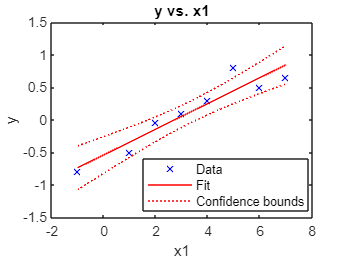

plot(mdl)

yfit = mdl.Coefficients.Estimate(2)*x+mdl.Coefficients.Estimate(1);

% Linear Algebra Method
X = [x; ones(1,length(x))]';
a = X\y';
yfit_a = a(1)*x + a(2);


**Minimize Objective**


$$\min_{a_0 ,a_1 } \sum_{i=1}^n {\left(y_i -y_{\textrm{fit},i} \right)}^2$$


where *n* is the length of *y* and $a_0$ and $a_1$ are adjusted to minimize the sum of the squared errors.

Report the parameter values, the $R^2$ value of fit, and display a plot of the results. Enforce a constraint with the intercept>-0.5 and show the effect of that constraint on the regression fit compared to the unconstrained least squares solution.

R_squared = rsq(y,yfit)

R_squared = 0.9098

**Curve Fitter**

1. Run the following or click on APPS in the Ribbon above, under Math, Statistics, and Optimization, click Curve Fitter. 

curveFitter

2. When the pop-up appears, click Select Data in the top left. Input x and y as X data and Y data, respectively and click close. 

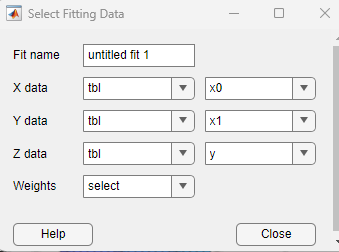

3. You can change the polynomial on the right hand side and view the R-squared error in the bottom right.

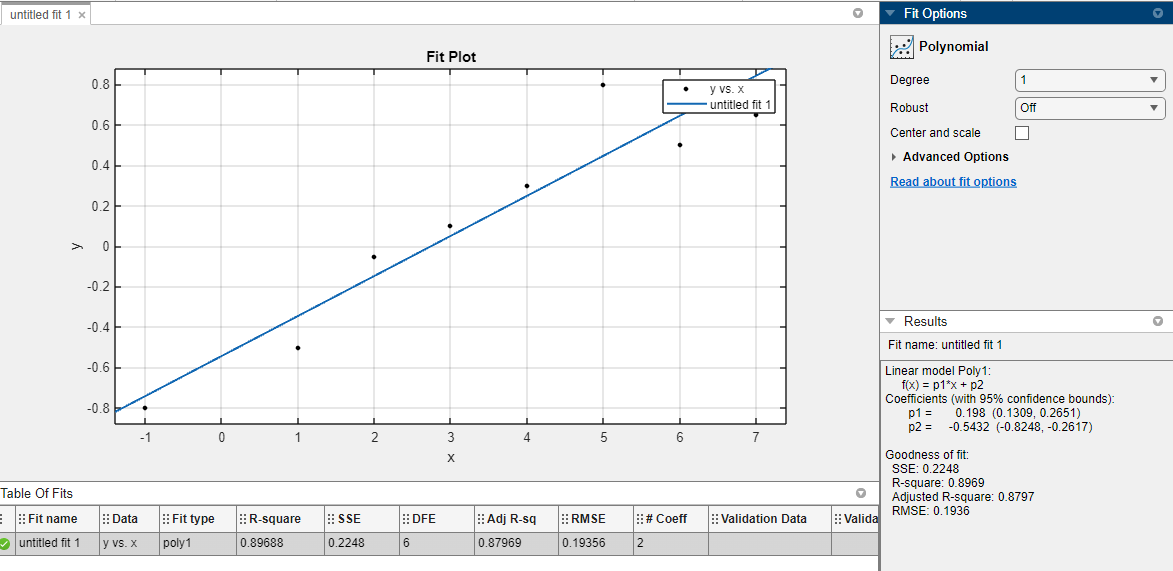

**Regression Learner**

Run the following or click on the APPS in the Ribbon above, under Machine Learning and Deep Learning, click Regression Learner. When the pop-up appears, start a new session by clicking on the New Session button in the top right. In Data Set Variable, select x and then click the button Use rows as variables. Under the Response, click From workspace and select y. Now click Start Session in the botton left. In the Ribbon under Models, select Linear Regression. Then select Train in the Ribbon. It will output a plot where you can view the summary by clicking on the summary tab.

regressionLearner

## Exercise 2: Multiple Linear Regression

**Objective:** Perform multiple linear regression on sample data with two inputs.

For linear regression, find unknown parameters *a**0*-*a**2* to minimize the difference between measured *y* and predicted *y**fit*.

**Data**

x0=[4,5,2,3,−1,1,6,7]

x1=[3,2,3,4,3,5,2,6]

y=[0.3,0.8,−0.05,0.1,−0.8,−0.5,0.5,0.65]

x0 = [4,5,2,3,-1,1,6,7];
x1 = [3,2,3,4, 3,5,2,6];
y = [0.3,0.8,-0.05,0.1,-0.8,-0.5,0.5,0.65];
one_array = ones(1,8);

**Linear Equation**


$$y_{\mathrm{fit}} =a_0 x_0 +a_1 x_1 +a_2$$


% Linear Algebra Method
X = [x0; x1; ones(1,length(x0))]';
a = X\y';
yfit = a(1)*x0 + a(2)*x1 + a(3);

% Model fit Method
arr = [x0', x1' y'];
tbl = array2table(arr);
tbl = renamevars(tbl,["arr1","arr2","arr3"],["x0","x1","y"]);
mdl = fitlm(tbl)

mdl = Linear regression model:
    y ~ 1 + x0 + x1

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)     -0.28825     0.18586    -1.5509       0.18162
    x0               0.20025    0.024256     8.2558    0.00042516
    x1             -0.075027    0.045782    -1.6388       0.16218


Number of observations: 8, Error degrees of freedom: 5
Root Mean Squared Error: 0.171
R-squared: 0.933,  Adjusted R-Squared: 0.906
F-statistic vs. constant model: 34.8, p-value = 0.00117

**Minimize Objective**


$$\min_{a_0 ,a_1 } \sum_{i=1}^n {\left(y_i -y_{\textrm{fit},i} \right)}^2$$


where *n* is the length of *y* and $a_0 -a_1$ are adjusted to minimize the sum of the squared errors.

Report the parameter values, the $R^2$ value of fit, and display a plot of the results.

fprintf('R^2 = %.2f\n',rsq(y,yfit))

R^2 = 0.94


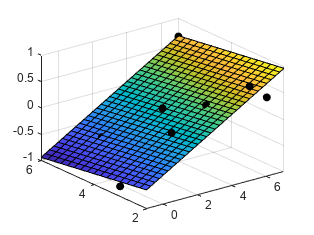


% plot data
figure
scatter3(x0,x1,y,'k','o','filled')
hold on
x0t = -1:0.25:7;
x1t = 2:0.25:6;
[X0,X1] = meshgrid(x0t,x1t);
Yt = a(1)*X0 + a(2)*X1 + a(3);
surf(X0,X1,Yt)
hold off

**Curve Fitter**

1. Run the following or click on APPS in the Ribbon above, under Math, Statistics, and Optimization, click Curve Fitter. 

curveFitter

2. When the pop-up appears, click Select Data in the top left. Input tbl and select the variables to be x0, x1, and y as X data, Y data, Z data, respectively and click close. 

3. You can view the R-squared error in the bottom right.

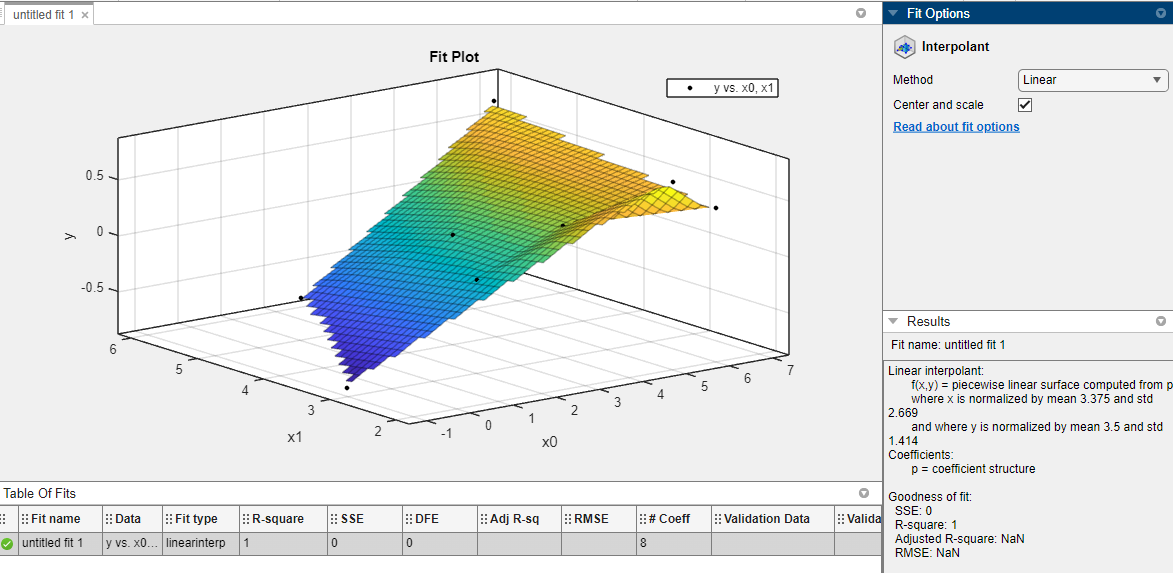

## Exercise 3: Scale-up

For large problems, it is important to know how a linear regression package performs with larger data sets on CPU and GPU hardware. We will only show two methods in this example of a linear fit for larger data sets.

Here is more information from MATLAB about large data sets: [Regression Strategies for Large Datasets - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/company/newsletters/articles/regression-strategies-for-large-datasets.html)

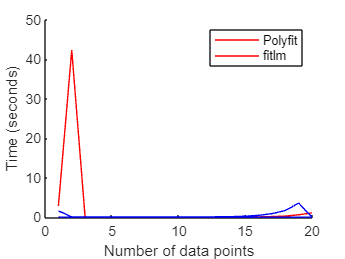

table = zeros(20);
table1 = zeros(20);

% Polyfit Method
test_time = 20.0;
w = rand();
b = rand();
n = 100;
start = tic;
i = 1;
while toc(start) <= test_time
    x = linspace(0,100,n);
    y = w * x + b;

    % Add noise
    noise = randn(1,n);
    y = y + noise;
    
    t0 = tic;
    polyfit(x,y,1);
    t1 = toc(t0);
    %fprintf('%d %f\n',n,t1)
    table(i) = t1;
    i = i + 1;

    n = n*2; % Double number of data points
end

% fitlm
test_time = 20.0;
w = rand();
b = rand();
n = 100;
start = tic;
i = 1;
while toc(start) <= test_time
    x = linspace(0,100,n);
    y = w * x + b;
    
    % Add Gaussian noise
    noise = randn(1,n);
    y = y + noise;

    t0 = tic;
    lm = fitlm(x',y');
    t1 = toc(t0);
    %fprintf('%d %d\n', n, t1);
    table1(i) = t1;
    i = i + 1;

    n = n * 2; % Double number of data points
end


figure
hold on
plot(table, 'r')
plot(table1, 'b')
xlabel('Number of data points')
ylabel('Time (seconds)')

legend('Polyfit', 'fitlm')

**Supplementary Functions**

function r2 = rsq(y1,y2)
    yresid = y1 - y2;
    SSresid = sum(yresid.*yresid);
    [V,~ ] = var(y1);
    [~,c]=size(y1);
    SStotal = c*V;
    r2 = 1 - SSresid./SStotal;
end